# **Iniciação Científica**

#### Tema: Análise de Eficiência de Desacopladores e Técnicas de Projeto de Controladores PI SISO para Processos de Moagem

**Voluntária IC:** Grazielle Amanda do Carmo Café

**Orientador:** Dr. Márcio Braga

close all
clearvars

## **Modelo descrito por Craig (2012)**

### Etapa 1: Descrição do Modelo

s = tf('s', 'TimeUnit', 'seconds');
G(1,1) = (0.105/(83*s+1));
Ga(1,1) = exp(-65*s);
Gd(1,1) = -65;

G(1,2) = (-0.082/(1766*s+1));
Ga(1,2) = exp(-80*s);
Gd(1,2) = -80;

G(1,3) = (-0.0575/(167*s+1));
Ga(1,3) = exp(-460*s);
Gd(1,3) = -460;

G(2,1) = (-0.0468/(1864*s+1));
Ga(2,1) = exp(-140*s);
Gd(2,1) = -140;

G(2,2) = (0.000122/s);
Ga(2,2) = 1; 
Gd(2,2) = 0;

G(2,3) = (0.115/(1981*s+1));
Ga(2,3)= exp(-120*s);
Gd(2,3) = -120;

G(3,1) = (0.00253/s);
Ga(3,1) = 1;
Gd(3,1) = 0;

G(3,2) = 0;
Ga(3,2) = 1;
Gd(3,1) = 0;

G(3,3) = (-0.00299/s);
Ga(3,3) = 1;
Gd(3,1) = 0;

% Função de transferência G:
G                       % Modelo sem atraso

G =
 
  From input 1 to output...
        0.105
   1:  --------
       83 s + 1
 
        -0.0468
   2:  ----------
       1864 s + 1
 
       0.00253
   3:  -------
          s
 
  From input 2 to output...
         -0.082
   1:  ----------
       1766 s + 1
 
       0.000122
   2:  --------
          s
 
   3:  0
 
  From input 3 to output...
        -0.0575
   1:  ---------
       167 s + 1
 
         0.115
   2:  ----------
       1981 s + 1
 
       -0.00299
   3:  --------
          s
 
Continuous-time transfer function.



Gdelay = Ga             % Atrasos presentes no modelo

Gdelay =
 
  From input 1 to output...
   1:  exp(-65*s) * (1)
 
   2:  exp(-140*s) * (1)
 
   3:  1
 
  From input 2 to output...
   1:  exp(-80*s) * (1)
 
   2:  1
 
   3:  1
 
  From input 3 to output...
   1:  exp(-460*s) * (1)
 
   2:  exp(-120*s) * (1)
 
   3:  1
 
Continuous-time transfer function.



Gmodel = G.*Gdelay      % Função de transferência G do modelo c/ atrasos

Gmodel =
 
  From input 1 to output...
                     0.105
   1:  exp(-65*s) * --------
                    83 s + 1
 
                      -0.0468
   2:  exp(-140*s) * ----------
                     1864 s + 1
 
       0.00253
   3:  -------
          s
 
  From input 2 to output...
                      -0.082
   1:  exp(-80*s) * ----------
                    1766 s + 1
 
       0.000122
   2:  --------
          s
 
   3:  0
 
  From input 3 to output...
                      -0.0575
   1:  exp(-460*s) * ---------
                     167 s + 1
 
                       0.115
   2:  exp(-120*s) * ----------
                     1981 s + 1
 
       -0.00299
   3:  --------
          s
 
Continuous-time transfer function.




% Não tem RHP (SPD - polos semi plano direito): 
zeros = tzero(pade(Gmodel))

zeros =   -0.1314 + 0.0000i
   0.0308 + 0.0000i
  -0.0168 + 0.0000i
  -0.0142 + 0.0000i
  -0.0088 + 0.0000i
  -0.0012 + 0.0003i
  -0.0012 - 0.0003i
  -0.0003 + 0.0000i
  -0.0006 + 0.0000i
  -0.0308 + 0.0000i


polos = pole(Gmodel)

polos =    -0.0120
   -0.0006
   -0.0060
   -0.0005
         0
   -0.0005
         0


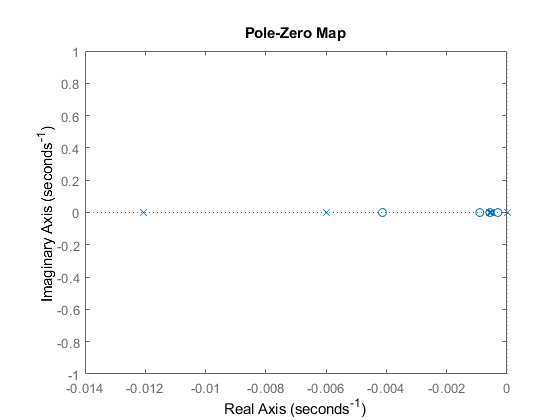

pzplot(Gmodel);

**Artigo sobre modelos com atraso e termo integrador**

### Desacoplador Estático

#### Teste 1 

% Comentário: uma matriz somente admite inversa se seu 
% determinante for diferente de zero
% 
% Gstatic = evalfr(Gmodel,0)
% determinant = det(Gstatic)
% Dstatic = inv(Gstatic);     % Erro: NaN
% out = Gmodel*Dstatic;
% step(out);


#### Teste 2

% D(1,1) = 1; 
% D(1,2) = dcgain(-Gmodel(1,2)/G(1,1));
% D(1,3) = dcgain(-Gmodel(1,3)/G(1,1));
% D(2,1) = dcgain(-Gmodel(2,1)/G(2,2));
% D(2,2) = 1; 
% D(2,3) = dcgain(-Gmodel(2,3)/G(2,2));
% D(3,1) = dcgain(-Gmodel(3,1)/G(3,3));
% D(3,2) = dcgain(-Gmodel(3,2)/G(3,3));
% D(3,3) = 1;
% 
% D
% out = G*D
% step(out)


#### **Teste 3**


% for x = 1:3
%     for y = 1:3
%         D(x,y) = (G(x,y)*G(x,x))
%                
%         if x == y
%          D(x,y) = 1
%         end
%         
%         if abs(dcgain(D(x,y))) < 1e-5
%             D(x,y) = 0
%         end            
%     end
% end
% 
% out = Gmodel*D
% plot(out)
